# CMM SV models

- Prepare stochastic volatility models

- Identify a SVAR using Cholesky

- Checking TV features of sigma in estimation/IRF/forecast



clear
close all
rehash path


addpath ../sandbox

addpath ../bear

## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("CCMMSV.csv");

estimStart = datex.m(1960,3);
estimEnd = datex.m(2021,3);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["RPI","DPCERA3M086SBEA", "INDPRO","CUMFNS","UNRATE", "PAYEMS", "CES0600000007",...
    "CES0600000008", "WPSFD49207", "PCEPI", "HOUST", "SP500", "EXUSUK", "GS5", "GS10", "BAAFFM"], ...
    units="", ...
    exogenous=[], ...
    order=12, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20 ...
    ...
);

dataH = model.DataHolder(meta, inputTbx);


## CCMM Stochastic-volatiliy models

Standard 


estimatorR1 = estimator.CCMMSV(meta,...
    Turningpoint = datex.m(2020,3));

modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);
modelR1.Estimator.Settings

ans =   CCMMSV with properties:

    HeteroskedasticityScale: 0.1500
               Turningpoint: 2020-03
                     Burnin: 0
                  Exogenous: [16×1 logical]
             BlockExogenous: 0
             Autoregression: [16×1 double]
                    Lambda1: 0.1000
                    Lambda2: 0.5000
                    Lambda3: 1
                    Lambda4: [16×1 double]
                    Lambda5: 1.0000e-03
         StabilityThreshold: Inf
     MaxNumUnstableAttempts: 1000


Outliers

estimatorR2 = estimator.CCMMSVO(meta,...
    Turningpoint = datex.m(2020,3));

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , stabilityThreshold=Inf ...
);
modelR2.Estimator.Settings

ans =   CCMMSVO with properties:

                OutlierFreq: 10
              PriorObsYears: 10
    HeteroskedasticityScale: 0.1500
               Turningpoint: 2020-03
                     Burnin: 0
                  Exogenous: [16×1 logical]
             BlockExogenous: 0
             Autoregression: [16×1 double]
                    Lambda1: 0.1000
                    Lambda2: 0.5000
                    Lambda3: 1
                    Lambda4: [16×1 double]
                    Lambda5: 1.0000e-03
         StabilityThreshold: Inf
     MaxNumUnstableAttempts: 1000


Outlieres & t-distributed shocks

estimatorR3 = estimator.CCMMSVOT(meta,...
    Turningpoint = datex.m(2020,3));

modelR3 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR3 ...
    , stabilityThreshold=Inf ...
);
modelR3.Estimator.Settings

ans =   CCMMSVOT with properties:

        QDiagonalLowerBound: 3
        QDiagonalUpperBound: 40
                OutlierFreq: 10
              PriorObsYears: 10
    HeteroskedasticityScale: 0.1500
               Turningpoint: 2020-03
                     Burnin: 0
                  Exogenous: [16×1 logical]
             BlockExogenous: 0
             Autoregression: [16×1 double]
                    Lambda1: 0.1000
                    Lambda2: 0.5000
                    Lambda3: 1
                    Lambda4: [16×1 double]
                    Lambda5: 1.0000e-03
         StabilityThreshold: Inf
     MaxNumUnstableAttempts: 1000


## Indentify a SVAR using Cholesky (without reordering)

Standard


identChol = identifier.Cholesky(order=[]);

modelS1 = model.Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();
info1 = modelS1.presample(10);


 Presampling model.Structural (CCMMSV) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                     B: [193×16 double]
                     F: [16×16 double]
             logLambda: [16×733 double]
               cholPhi: [136×1 double]
             LogLambda: [16×733 double]
              sigmaAvg: [16×16 double]
               sigma_t: {733×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [16×16 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [16×16 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =    -0.3795    0.0037   -0.0283   -0.0004   -0.0000   -0.0006    0.0003   -0.0020   -0.0087   -0.0072   -0.0001    0.0514    0.0398    0.0006   -0.0002   -0.0004
    0.0189   -0.0075   -0.0223    0.0010   -0.0002    0.0135   -0.0001    0.0012    0.0141    0.0011    0.0001   -0.0958   -0.0271   -0.0001    0.0002    0.0002
   -0.0034   -0.0128    0.3242    0.0034    0.0004   -0.0002   -0.0005    0.0015   -0.0165   -0.0024   -0.0000    0.0867   -0.0531   -0.0003   -0.0003   -0.0004
   -0.1709    0.0635   -0.3711    0.9507   -0.0143    0.0795    0.0162    0.0679   -0.0912   -0.0285   -0.0004   -0.9421    0.6705    0.0019   -0.0014   -0.0067
   -0.7393    0.0445   -0.5146    0.0400    0.9181   -0.0257    0.0247    0.3619   -0.4674    0.0945   -0.0029    1.0867   -0.6339    0.0031   -0.0034   -0.0076
   -0.0085   -0.0601    0.0811    0.0003   -0.0056    0.1298   -0.0029   -0.0022   -0.0333    0.0098    0.0001   -0.1125    0.1764    0.0015   -0.0004    0.0006
   -0.1056    0.2685   -1.23

modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =    -0.3795    0.0037   -0.0283   -0.0004   -0.0000   -0.0006    0.0003   -0.0020   -0.0087   -0.0072   -0.0001    0.0514    0.0398    0.0006   -0.0002   -0.0004
    0.0189   -0.0075   -0.0223    0.0010   -0.0002    0.0135   -0.0001    0.0012    0.0141    0.0011    0.0001   -0.0958   -0.0271   -0.0001    0.0002    0.0002
   -0.0034   -0.0128    0.3242    0.0034    0.0004   -0.0002   -0.0005    0.0015   -0.0165   -0.0024   -0.0000    0.0867   -0.0531   -0.0003   -0.0003   -0.0004
   -0.1709    0.0635   -0.3711    0.9507   -0.0143    0.0795    0.0162    0.0679   -0.0912   -0.0285   -0.0004   -0.9421    0.6705    0.0019   -0.0014   -0.0067
   -0.7393    0.0445   -0.5146    0.0400    0.9181   -0.0257    0.0247    0.3619   -0.4674    0.0945   -0.0029    1.0867   -0.6339    0.0031   -0.0034   -0.0076
   -0.0085   -0.0601    0.0811    0.0003   -0.0056    0.1298   -0.0029   -0.0022   -0.0333    0.0098    0.0001   -0.1125    0.1764    0.0015   -0.0004    0.0006
   -0.1056    0.2685   -1.23

Outliers


modelS2 = model.Structural(reducedForm=modelR2, identifier=identChol);
modelS2.initialize();
info2 = modelS2.presample(10);


 Presampling model.Structural (CCMMSVO) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS2.Presampled{1}

ans = struct with fields:
                     B: [193×16 double]
                     F: [16×16 double]
             logLambda: [16×733 double]
               cholPhi: [136×1 double]
                     O: [16×733 double]
                 probO: [16×1 double]
              sigmaAvg: [16×16 double]
               sigma_t: {733×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [16×16 double]


modelS2.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [16×16 double]


modelS2.Presampled{1}.IdentificationDraw.A{1,1}

ans =    -0.3913   -0.0123   -0.0122   -0.0006   -0.0004   -0.0047   -0.0008    0.0070    0.0020   -0.0006    0.0001    0.0383    0.0021    0.0003    0.0002   -0.0006
    0.0109   -0.0027    0.0042    0.0005    0.0002    0.0035    0.0003    0.0066   -0.0025   -0.0044   -0.0000   -0.0623   -0.0203    0.0002   -0.0001    0.0009
   -0.0055   -0.0086    0.3384    0.0005   -0.0005   -0.0053   -0.0005   -0.0029   -0.0113   -0.0010   -0.0002   -0.0990    0.0237    0.0001    0.0002   -0.0014
   -0.1886   -0.0631   -0.3707    0.9994   -0.0055    0.1512    0.0141    0.2189    0.2496   -0.0359    0.0004    2.1226   -0.3006    0.0085   -0.0080   -0.0067
   -0.4547   -0.2697    0.2637   -0.0101    0.9540   -0.2893    0.0266    0.4089    0.3725    0.1719   -0.0017   -1.4369   -0.2152   -0.0216   -0.0234    0.0059
   -0.0357   -0.0089    0.0691    0.0030   -0.0015    0.1199   -0.0034   -0.0173    0.0071    0.0121    0.0002    0.0416    0.0839   -0.0010   -0.0010    0.0022
   -0.0935   -0.2652   -0.91

modelS2.Presampled{1}.IdentificationDraw.A{2,1}

ans =    -0.3913   -0.0123   -0.0122   -0.0006   -0.0004   -0.0047   -0.0008    0.0070    0.0020   -0.0006    0.0001    0.0383    0.0021    0.0003    0.0002   -0.0006
    0.0109   -0.0027    0.0042    0.0005    0.0002    0.0035    0.0003    0.0066   -0.0025   -0.0044   -0.0000   -0.0623   -0.0203    0.0002   -0.0001    0.0009
   -0.0055   -0.0086    0.3384    0.0005   -0.0005   -0.0053   -0.0005   -0.0029   -0.0113   -0.0010   -0.0002   -0.0990    0.0237    0.0001    0.0002   -0.0014
   -0.1886   -0.0631   -0.3707    0.9994   -0.0055    0.1512    0.0141    0.2189    0.2496   -0.0359    0.0004    2.1226   -0.3006    0.0085   -0.0080   -0.0067
   -0.4547   -0.2697    0.2637   -0.0101    0.9540   -0.2893    0.0266    0.4089    0.3725    0.1719   -0.0017   -1.4369   -0.2152   -0.0216   -0.0234    0.0059
   -0.0357   -0.0089    0.0691    0.0030   -0.0015    0.1199   -0.0034   -0.0173    0.0071    0.0121    0.0002    0.0416    0.0839   -0.0010   -0.0010    0.0022
   -0.0935   -0.2652   -0.91

Outliers &t-distribution


modelS3 = model.Structural(reducedForm=modelR3, identifier=identChol);
modelS3.initialize();
info3 = modelS3.presample(10);


 Presampling model.Structural (CCMMSVOT) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS3.Presampled{1}

ans = struct with fields:
                     B: [193×16 double]
                     F: [16×16 double]
             logLambda: [16×733 double]
               cholPhi: [136×1 double]
                     O: [16×733 double]
                 probO: [16×1 double]
                     Q: [16×733 double]
                  dofQ: [16×1 double]
              sigmaAvg: [16×16 double]
               sigma_t: {733×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [16×16 double]


modelS3.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [16×16 double]


modelS3.Presampled{1}.IdentificationDraw.A{1,1}

ans =    -0.3815   -0.0015   -0.0220   -0.0001   -0.0004   -0.0107   -0.0006   -0.0016   -0.0050   -0.0029   -0.0001   -0.0004    0.0322    0.0006    0.0000   -0.0009
    0.0189   -0.0155   -0.0131   -0.0005    0.0005    0.0141    0.0001    0.0032    0.0023    0.0047    0.0000   -0.0404    0.0075    0.0001    0.0002   -0.0004
   -0.0472    0.0284    0.2986    0.0062   -0.0008    0.0061   -0.0006   -0.0016   -0.0094    0.0089    0.0002    0.0287   -0.0357   -0.0001    0.0004   -0.0001
    0.6939   -0.2287    0.2131    0.9187   -0.0037    0.0985    0.0167    0.1138   -0.3548   -0.1375   -0.0012    0.0041    0.3137    0.0059    0.0013   -0.0094
   -0.7575   -0.2140    0.4416    0.0601    0.8943   -0.0819    0.0298    0.2307    0.1817    0.0335   -0.0033    0.7631   -0.6850    0.0142   -0.0011   -0.0166
   -0.0045   -0.0456    0.0658    0.0023   -0.0007    0.1317   -0.0024   -0.0178    0.0410    0.0075   -0.0005   -0.1936    0.0691    0.0010   -0.0010   -0.0002
    0.3298   -0.1066   -1.17

modelS3.Presampled{1}.IdentificationDraw.A{2,1}

ans =    -0.3815   -0.0015   -0.0220   -0.0001   -0.0004   -0.0107   -0.0006   -0.0016   -0.0050   -0.0029   -0.0001   -0.0004    0.0322    0.0006    0.0000   -0.0009
    0.0189   -0.0155   -0.0131   -0.0005    0.0005    0.0141    0.0001    0.0032    0.0023    0.0047    0.0000   -0.0404    0.0075    0.0001    0.0002   -0.0004
   -0.0472    0.0284    0.2986    0.0062   -0.0008    0.0061   -0.0006   -0.0016   -0.0094    0.0089    0.0002    0.0287   -0.0357   -0.0001    0.0004   -0.0001
    0.6939   -0.2287    0.2131    0.9187   -0.0037    0.0985    0.0167    0.1138   -0.3548   -0.1375   -0.0012    0.0041    0.3137    0.0059    0.0013   -0.0094
   -0.7575   -0.2140    0.4416    0.0601    0.8943   -0.0819    0.0298    0.2307    0.1817    0.0335   -0.0033    0.7631   -0.6850    0.0142   -0.0011   -0.0166
   -0.0045   -0.0456    0.0658    0.0023   -0.0007    0.1317   -0.0024   -0.0178    0.0410    0.0075   -0.0005   -0.1936    0.0691    0.0010   -0.0010   -0.0002
    0.3298   -0.1066   -1.17

## Impulse responses

Standard

respTbx1 = modelS1.simulateResponses();
respTbx1 = tablex.apply(respTbx1, prctileFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 32×256 timetable
     Time                RPI___shock1                         RPI___shock2                           RPI___shock3                            RPI___shock4                             RPI___shock5                            RPI___shock6                            RPI___shock7                            RPI___shock8                           RPI___shock9                           RPI___shock10                          RPI___shock11                         RPI___shock12                          RPI___shock13                           RPI___shock14                            RPI___shock15                            RPI___shock16                     DPCERA3M086SBEA___shock

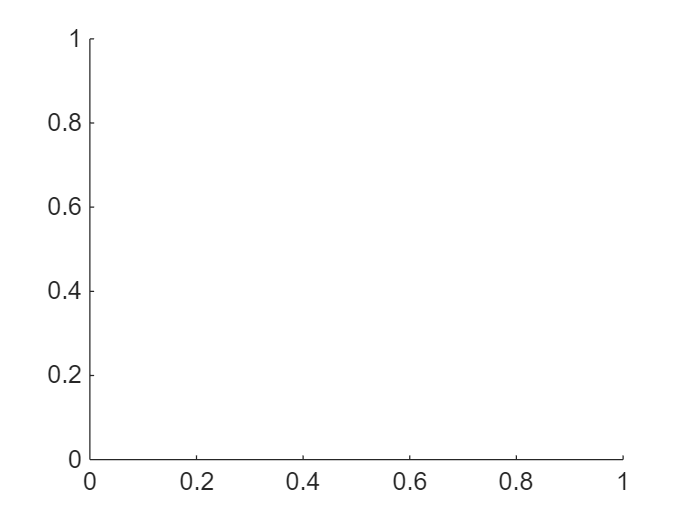

Error using  .  (line 229)
Unrecognized table variable name 'YER___DEM'.

Error in tablex.retrieveDataAsCellArray (line 38)
        data = inTable.(name);

Error in tablex


tablex.plot(respTbx1,"YER___DEM")

## Unconditional forecast 


fcastStart = datex.shift(modelS1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Standard

fcastTbx1 = modelS1.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);
fcastPrctileTbx1 = tablex.flatten(fcastPrctileTbx1);

fcastTbx1

tablex.plot( ...
    fcastPrctileTbx1, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);